# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.3 三维绘图

#### 2.3.1 给球面贴背景图

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

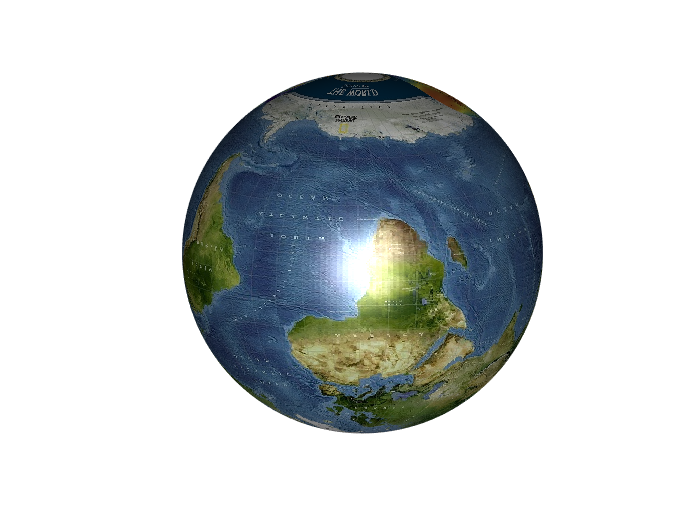

clear;clc;
% 获取到颜色
[all_themes, all_colors] = GetColors();
% 读取地图文件
image = imread('data\WorldMap.jpg'); 
% 生成一个球面数据
[x, y, z] = sphere(200);
% 绘制球体
p = surf(x, y, z); 
% 去网格线
shading interp;
p.CData = image; 
% 纹理贴图
p.FaceColor = "texturemap"; 
axis equal;
axis off
% 光源，看起来更有立体感
% light
% lighting gouraud
% 光源颜色
handle = light('Color', 'w');
t = 0;
while t < 100
    t = t + 1;
    view([t 10]);
    lightangle(handle, t, 0);
    pause(0.01);
end